%Generacja systemu
% r_min=-5;
% r_max=5;
% r=(r_min-r_max).*rand()+r_max;
% b0=2*r;
% r=(r_min-r_max).*rand()+r_max;
% a0=2*r;
% r=(r_min-r_max).*rand()+r_max;
% a1=2*r;
% r=(r_min-r_max).*rand()+r_max;
% a2=2*r;
% r=(r_min-r_max).*rand()+r_max;
% a3=2*r;

a3=1;
a2=6;
a1=2;
a0=1;
b0=1;
b1=1;
b2=1;

L=[b2 b1 b0];
M=[a3 a2 a1 a0];
sys=tf(L,M)


sys =
 
       s^2 + s + 1
  ---------------------
  s^3 + 6 s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


[A, B, C, D]=tf2ss(L,M)

A =     -6    -2    -1
     1     0     0
     0     1     0


B =      1
     0
     0


C =      1     1     1


D = 0

A=[0 0 -1;
   1 0 -2;
   0 1 -4];
B=[1;1;1];
C=[0 0 1];
[L1, M1]=ss2tf(A,B,C,D)

L1 =          0    1.0000    1.0000    1.0000


% norm(A,"fro")
% step(sys,0:0.1:30);

%Regulator

Q=[7 0 0;
   0 1 0;
   0 0 5];
[K, S, poles]=lqr(A,B,Q,[1])

K =     2.3115    0.4678   -0.0245


S =     3.7456   -0.8286   -0.6056
   -0.8286    1.6870   -0.3906
   -0.6056   -0.3906    0.9716


poles =   -0.9698 + 0.1834i
  -0.9698 - 0.1834i
  -4.8152 + 0.0000i


Ac=A-B*K;
% K=[0 0 0];

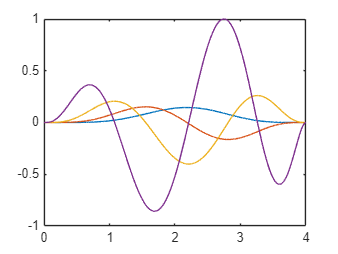

%funkcja phi /znormalizować
h=4;
step_size=0.001;
t=0:step_size:h-step_size;
N=6;
M=5;
% global phi phi_1 phi_2;
phi=(t.^N).*((h-t).^M);

% phi_1=diff(phi)/step_size;
phi_1=(N*t.^(N-1)).*((h-t).^M)-(M*t.^N).*(h-t).^(M-1);

% phi_2=diff(phi_1)/step_size;
phi_2=(M*t.^N).*((h-t).^(M-2)).*(M-1)-(2*M*N*t.^(N-1)).*((h-t).^(M-1))+(N*t.^(N-2).*((h-t).^M)*(N-1));

phi_3=3*M*N*t.^(N - 1).*(h - t).^(M - 2).*(M - 1) - M*t.^N.*(h - t).^(M - 3).*(M - 1).*(M - 2) - 3*M*N*t.^(N - 2).*(h - t).^(M - 1).*(N - 1) + N*t.^(N - 3).*(h - t).^M.*(N - 1).*(N - 2); 
phi=phi/max(abs(phi_3));

phi_1=phi_1/max(abs(phi_3));
phi_2=phi_2/max(abs(phi_3));
phi_3=phi_3/max(abs(phi_3));
plot(t,phi,t,phi_1,t,phi_2,t,phi_3)

trapz(t,phi,2)

ans = 0.2042

trapz(t,phi_1,2)

ans = 7.0698e-16

trapz(t,phi_2,2)

ans = -2.7113e-12

trapz(t,phi_3,2)

ans = 8.2663e-09

conv_size=length(phi);
T_iD=7/step_size;

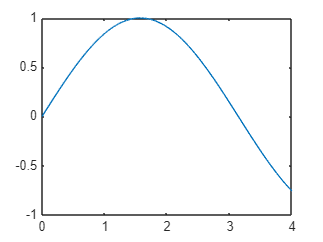

plot(t,sin(t))

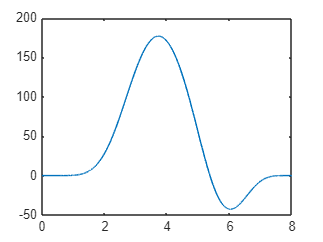

% plot(t,cumtrapz(t,sin(t)))
vec=0:step_size:(length(conv(sin(t),phi))-1)*step_size;
conv_plot=conv(sin(t),phi);
plot(vec,conv_plot)

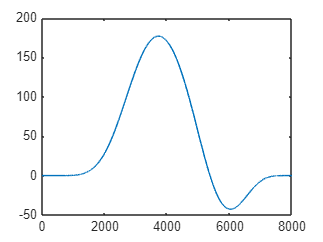


clear splot_1 splot_2
sinus=sin(t);
for j=1:length(sinus)+length(phi)-2
    clear splot_1
    if j<=length(sinus)        
        splot_1=sinus(1:j).*fliplr(phi(1:j));        
    else
        splot_1=sinus((j-length(sinus)):end).*fliplr(phi((j-length(sinus)):end));
    end
    splot_2(j)=trapz(step_size,splot_1,2);
end

SINUS=fft([sinus zeros(1,length(phi)-1)]);
PHI=fft([phi zeros(1,length(sinus)-1)]);
plot(ifft(SINUS.*PHI))

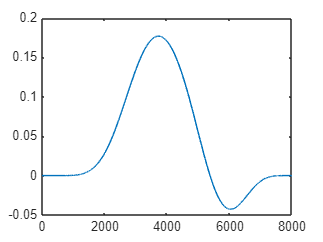


% plot(splot_1)
% xlim([0 400])
plot(splot_2)

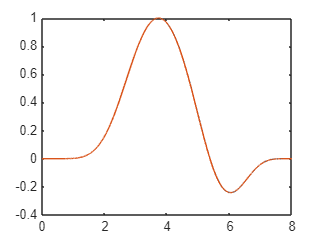

plot(vec(1:end-1),splot_2/max(splot_2),vec,conv_plot/max(conv_plot))

% xlim([0 400])
% plot(vec,conv(sin(t),phi_1))
% plot(cumtrapz(vec,conv(sin(t),phi),2))
% plot(vec,cumtrapz(vec,conv(sin(t),phi_1),2)*4.25,vec,conv(sin(t),phi))

K =     0.9275    0.7740   -0.3264


S =     0.9974   -0.0698   -0.1259
   -0.0698    0.8438   -0.2005
   -0.1259   -0.2005    0.1623


poles =   -1.0205 + 0.2485i
  -1.0205 - 0.2485i
  -5.6604 + 0.0000i


syms t N h M
phi_anal(t) = (t^N)*((h-t)^M);
phi_anal1(t)=diff(phi_anal,t)

$$phi\_anal1(t) = N\,t^{N-1}\,{\left(h-t\right)}^{M}-M\,t^{N}\,{\left(h-t\right)}^{M-1}$$

phi_anal2(t)=diff(phi_anal1,t)

$$phi\_anal2(t) = M\,t^{N}\,{\left(h-t\right)}^{M-2}\,\left(M-1\right)-2\,M\,N\,t^{N-1}\,{\left(h-t\right)}^{M-1}+N\,t^{N-2}\,{\left(h-t\right)}^{M}\,\left(N-1\right)$$

phi_anal3(t)=diff(phi_anal2,t)

$$phi\_anal3(t) = 3\,M\,N\,t^{N-1}\,{\left(h-t\right)}^{M-2}\,\left(M-1\right)-M\,t^{N}\,{\left(h-t\right)}^{M-3}\,\left(M-1\right)\,\left(M-2\right)-3\,M\,N\,t^{N-2}\,{\left(h-t\right)}^{M-1}\,\left(N-1\right)+N\,t^{N-3}\,{\left(h-t\right)}^{M}\,\left(N-1\right)\,\left(N-2\right)$$

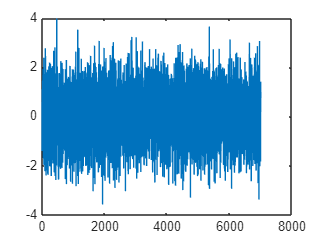

%simulate system
x0 = [0;0;0];             % Initial state (N=2)
Ns = 11/step_size; 	    % Number of sample times to simulate
% u = sin(0:step_size:(T_iD-1)*step_size); % Input signal (an impulse at time 0)
% u = sawtooth(0:step_size:(T_iD-1)*step_size);
u = randn(1,7000);

% u = out.ScopeData.signals(2).values(1:7000);
y = zeros(T_iD,1);        % Preallocate output signal for n=0:Ns-1

% Perform the system simulation:
% x = x0;                % Set initial state
% x_p = x0;
% for n=1:Ns           % Iterate through time
%   y(n) = C*x_p + D*u(n); % Output for time n-1
%   x(:,end) = A*x_p + B*u(n);    % State transitions to time n
%   x = [x [0;0;0]];
%   x_p = trapz([0:step_size:(size(x,2)-2)*step_size],x(:,1:end-1),2);
% end
t=0:step_size:(length(y)-1)*step_size;
y=lsim(sys,u,t)+0.005*randn([length(u) 1]);
% y = out.ScopeData.signals(1).values(1:7000);

% u=u+0.005*randn([1 length(u)]);
plot(u)

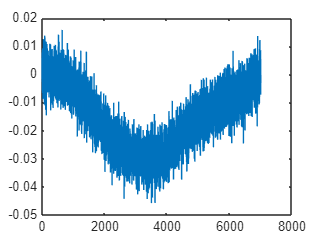

plot(y')

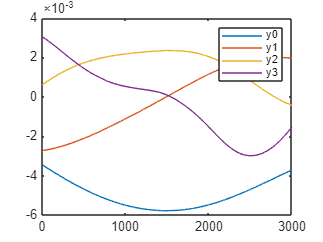

%evaluate method
t_=0:step_size:((conv_size-1)*step_size);
for n=1:T_iD-conv_size
    y0(n)=trapz(t_,(y(n:conv_size-1+n).*flip(phi)'),1);
    y1(n)=trapz(t_,(y(n:conv_size-1+n).*flip(phi_1)'),1);
    y2(n)=trapz(t_,(y(n:conv_size-1+n).*flip(phi_2)'),1);
    y3(n)=trapz(t_,(y(n:conv_size-1+n).*flip(phi_3)'),1);

    u0(n)=trapz(t_,(u(n:conv_size-1+n).*flip(phi)),2);
    u1(n)=trapz(t_,(u(n:conv_size-1+n).*flip(phi_1)),2);
    u2(n)=trapz(t_,(u(n:conv_size-1+n).*flip(phi_2)),2);
    u3(n)=trapz(t_,(u(n:conv_size-1+n).*flip(phi_3)),2);

    % y0(n)=trapz((y(n:conv_size-1+n).*flipud(phi)'),1);
    % y1(n)=trapz((y(n:conv_size-1+n).*flipud(phi_1)'),1);
    % y2(n)=trapz((y(n:conv_size-1+n).*flipud(phi_2)'),1);
    % y3(n)=trapz((y(n:conv_size-1+n).*flipud(phi_3)'),1);
    % 
    % u0(n)=trapz((u(n:conv_size-1+n).*flipud(phi)),2);
    % u1(n)=trapz((u(n:conv_size-1+n).*flipud(phi_1)),2);
    % u2(n)=trapz((u(n:conv_size-1+n).*flipud(phi_2)),2);
    % u3(n)=trapz((u(n:conv_size-1+n).*flipud(phi_3)),2);
end

% y0_=temp(length(phi):end-length(phi))*step_size;
% y0=y0/step_size;
% y1=y1/step_size;
% y2=y2/step_size;
% y3=y3/step_size;
% u0=u0/step_size;
% u1=u1/step_size;
% u2=u2/step_size;
% u3=u3/step_size;

% y0=fliplr(y0);
% y1=fliplr(y1);
% y2=fliplr(y2);
% y3=fliplr(y3);
% u0=fliplr(u0);
% u1=fliplr(u1);
% u2=fliplr(u2);
% u3=fliplr(u3);

% temp=conv(y,phi);
% y0=transpose(temp(length(phi):end-length(phi))*step_size);
% temp=conv(y,phi_1);
% y1=transpose(temp(length(phi):end-length(phi))*step_size);
% temp=conv(y,phi_2);
% y2=transpose(temp(length(phi):end-length(phi))*step_size);
% temp=conv(y,phi_3);
% y3=transpose(temp(length(phi):end-length(phi))*step_size);
% temp=conv(u,phi);
% u0=temp(length(phi):end-length(phi))*step_size;
% temp=conv(u,phi_1);
% u1=temp(length(phi):end-length(phi))*step_size;
% temp=conv(u,phi_2);
% u2=temp(length(phi):end-length(phi))*step_size;
% temp=conv(u,phi_3);
% u3=temp(length(phi):end-length(phi))*step_size;

% y0=transpose(conv(y,phi)*step_size);
% y1=transpose(conv(y,phi_1)*step_size);
% y2=transpose(conv(y,phi_2)*step_size);
% y3=transpose(conv(y,phi_3)*step_size);
% u0=conv(u,phi)*step_size;
% u1=conv(u,phi_1)*step_size;
% u2=conv(u,phi_2)*step_size;
% u3=conv(u,phi_3)*step_size;

plot(y0)
hold on
plot(y1)
plot(y2)
plot(y3)
legend('y0','y1','y2','y3')
hold off

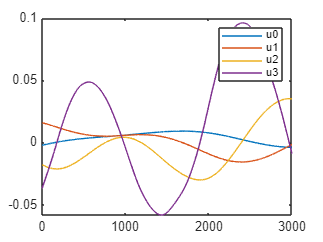

plot(u0)
hold on
plot(u1)
plot(u2)
plot(u3)
legend('u0','u1','u2','u3')
hold off

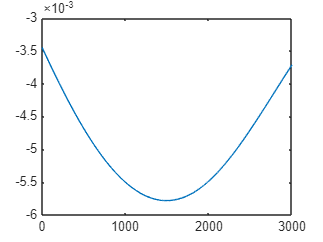

plot(y0)
hold on
% plot([zeros([length(phi) 1]); y0_; zeros([length(phi) 1])])
% plot(temp*step_size)
hold off

%macierz Gramma
t=0:step_size:((length(y0)-1)*step_size);
%         g11=trapz(t,y0.*y0,2);
%         g12=trapz(t,y0.*y1,2);
%         g13=trapz(t,y0.*y2,2);
%         g14=trapz(t,y0.*y3,2);
%         g15=trapz(t,y0.*u0,2);
%         g16=trapz(t,y0.*u1,2);
%         g17=trapz(t,y0.*u2,2);
%         g18=trapz(t,y0.*u3,2);
% 
% %         g21=trapz(t,y1.*y0,1);
%         g22=trapz(t,y1.*y1,2);
%         g23=trapz(t,y1.*y2,2);
%         g24=trapz(t,y1.*y3,2);
%         g25=trapz(t,y1.*u0,2);
%         g26=trapz(t,y1.*u1,2);
%         g27=trapz(t,y1.*u2,2);
%         g28=trapz(t,y1.*u3,2);
% 
% %         g31=trapz(t,y2.*y0,1);
% %         g32=trapz(t,y2.*y1,1);
%         g33=trapz(t,y2.*y2,2);
%         g34=trapz(t,y2.*y3,2);
%         g35=trapz(t,y2.*u0,2);
%         g36=trapz(t,y2.*u1,2);
%         g37=trapz(t,y2.*u2,2);
%         g38=trapz(t,y2.*u3,2);
% 
% %         g41=trapz(t,y3.*y0,1);
% %         g42=trapz(t,y3.*y1,1);
% %         g43=trapz(t,y3.*y2,1);
%         g44=trapz(t,y3.*y3,2);
%         g45=trapz(t,y3.*u0,2);
%         g46=trapz(t,y3.*u1,2);
%         g47=trapz(t,y3.*u2,2);
%         g48=trapz(t,y3.*u3,2);
% 
% %         g51=trapz(t,u0.*y0,1);
% %         g52=trapz(t,u0.*y1,1);
% %         g53=trapz(t,u0.*y2,1);
% %         g54=trapz(t,u0.*y3,1);
%         g55=trapz(t,u0.*u0,2);
%         g56=trapz(t,u0.*u1,2);
%         g57=trapz(t,u0.*u2,2);
%         g58=trapz(t,u0.*u3,2);
% 
%         % g61=trapz(t,u1.*y0,1);
%         % g62=trapz(t,u1.*y1,1);
%         % g63=trapz(t,u1.*y2,1);
%         % g64=trapz(t,u1.*y3,1);
%         % g65=trapz(t,u1.*u0,1);
%         g66=trapz(t,u1.*u1,2);
%         g67=trapz(t,u1.*u2,2);
%         g68=trapz(t,u1.*u3,2);
%         % 
%         % g71=trapz(t,u2.*y0,1);
%         % g72=trapz(t,u2.*y1,1);
%         % g73=trapz(t,u2.*y2,1);
%         % g74=trapz(t,u2.*y3,1);
%         % g75=trapz(t,u2.*u0,1);
%         % g76=trapz(t,u2.*u1,1);
%         g77=trapz(t,u2.*u2,2);
%         g78=trapz(t,u2.*u3,2);
%         % 
%         % g81=trapz(t,u3.*y0,1);
%         % g82=trapz(t,u3.*y1,1);
%         % g83=trapz(t,u3.*y2,1);
%         % g84=trapz(t,u3.*y3,1);
%         % g85=trapz(t,u3.*u0,1);
%         % g86=trapz(t,u3.*u1,1);
%         % g87=trapz(t,u3.*u2,1);
%         g88=trapz(t,u3.*u3,2);
        
        % g11=trapz(step_size,y0.*y0,2);
        % g12=trapz(step_size,y0.*y1,2);
        % g13=trapz(step_size,y0.*y2,2);
        % g14=trapz(step_size,y0.*y3,2);
        % g15=trapz(step_size,y0.*u0,2);
        % g16=trapz(step_size,y0.*u1,2);
        % g17=trapz(step_size,y0.*u2,2);
        % g18=trapz(step_size,y0.*u3,2);
        % 
        % g22=trapz(step_size,y1.*y1,2);
        % g23=trapz(step_size,y1.*y2,2);
        % g24=trapz(step_size,y1.*y3,2);
        % g25=trapz(step_size,y1.*u0,2);
        % g26=trapz(step_size,y1.*u1,2);
        % g27=trapz(step_size,y1.*u2,2);
        % g28=trapz(step_size,y1.*u3,2);
        % 
        % g33=trapz(step_size,y2.*y2,2);
        % g34=trapz(step_size,y2.*y3,2);
        % g35=trapz(step_size,y2.*u0,2);
        % g36=trapz(step_size,y2.*u1,2);
        % g37=trapz(step_size,y2.*u2,2);
        % g38=trapz(step_size,y2.*u3,2);
        % 
        % g44=trapz(step_size,y3.*y3,2);
        % g45=trapz(step_size,y3.*u0,2);
        % g46=trapz(step_size,y3.*u1,2);
        % g47=trapz(step_size,y3.*u2,2);
        % g48=trapz(step_size,y3.*u3,2);
        % 
        % g55=trapz(step_size,u0.*u0,2);
        % g56=trapz(step_size,u0.*u1,2);
        % g57=trapz(step_size,u0.*u2,2);
        % g58=trapz(step_size,u0.*u3,2);
        % 
        % g66=trapz(step_size,u1.*u1,2);
        % g67=trapz(step_size,u1.*u2,2);
        % g68=trapz(step_size,u1.*u3,2);
        % 
        % g77=trapz(step_size,u2.*u2,2);
        % g78=trapz(step_size,u2.*u3,2);
        % 
        % g88=trapz(step_size,u3.*u3,2);


G_ = nan(8);

for i = 1:4
    for j = 1:4
        G_(i,j) = eval("dot(y" + string(i-1) + ",y" + string(j-1) + ")");
    end
end



        g11=dot(y0,y0);
        g12=dot(y0,y1);
        g13=dot(y0,y2);
        g14=dot(y0,y3);
        g15=dot(y0,u0);
        g16=dot(y0,u1);
        g17=dot(y0,u2);
        g18=dot(y0,u3);

        g22=dot(y1,y1);
        g23=dot(y1,y2);
        g24=dot(y1,y3);
        g25=dot(y1,u0);
        g26=dot(y1,u1);
        g27=dot(y1,u2);
        g28=dot(y1,u3);

        g33=dot(y2,y2);
        g34=dot(y2,y3);
        g35=dot(y2,u0);
        g36=dot(y2,u1);
        g37=dot(y2,u2);
        g38=dot(y2,u3);

        g44=dot(y3,y3);
        g45=dot(y3,u0);
        g46=dot(y3,u1);
        g47=dot(y3,u2);
        g48=dot(y3,u3);

        g55=dot(u0,u0);
        g56=dot(u0,u1);
        g57=dot(u0,u2);
        g58=dot(u0,u3);

        g66=dot(u1,u1);
        g67=dot(u1,u2);
        g68=dot(u1,u3);

        g77=dot(u2,u2);
        g78=dot(u2,u3);

        g88=dot(u3,u3);

        G=[g11 g12 g13 g14 -g15 -g16 -g17 -g18;
           g12 g22 g23 g24 -g25 -g26 -g27 -g28;
           g13 g23 g33 g34 -g35 -g36 -g37 -g38;
           g14 g24 g34 g44 -g45 -g46 -g47 -g48;
           -g15 -g25 -g35 -g45 g55 g56 g57 g58;
           -g16 -g26 -g36 -g46 g56 g66 g67 g68;
           -g17 -g27 -g37 -g47 g57 g67 g77 g78;
           -g18 -g28 -g38 -g48 g58 g68 g78 g88]

        % G=[g11 g12 g13 g14 -g15 -g16 -g17 ;
        %    g12 g22 g23 g24 -g25 -g26 -g27 ;
        %    g13 g23 g33 g34 -g35 -g36 -g37 ;
        %    g14 g24 g34 g44 -g45 -g46 -g47 ;
        %    -g15 -g25 -g35 -g45 g55 g56 g57;
        %    -g16 -g26 -g36 -g46 g56 g66 g67;
        %    -g17 -g27 -g37 -g47 g57 g67 g77;]

         % G=[g11 g12 g13 g14 -g15;
         %   g12 g22 g23 g24 -g25;
         %   g13 g23 g33 g34 -g35;
         %   g14 g24 g34 g44 -g45;
         %   -g15 -g25 -g35 -g45 g55;]

% G=abs(G);
[V, De]=eig(G)
% V=abs(V);
format long
I=[0 0 0 0 0 0 0 0];
        M=[1e6 1e6 1e6 1e6 1e6 1e6 1e6 1e6];
        De=real(De);
        V=real(V);
        for j=1:length(De)
            for i=1:length(De)
                if i==j
                    M(j)=De(i,j);
                    I(j)=i;
                end
            end
        end
        ind=1;
        temp_min=1e6;
        for i=1:length(M)
            if  M(i)<temp_min %&& abs(M(i))>1e-10 
                ind=i;
                temp_min=M(ind);
            end
        end
oa=[V(4,ind) V(3,ind) V(2,ind) V(1,ind)]'
ob=[V(8,ind) V(7,ind) V(6,ind) V(5,ind)]'
% ob=[V(7,ind) V(6,ind) V(5,ind)]'

det(G(1:2,1:2))

Unrecognized function or variable 'G'.

det(G(1:3,1:3))
det(G(1:4,1:4))
det(G(1:5,1:5))
det(G(1:6,1:6))
det(G(1:7,1:7))
det(G(1:8,1:8))